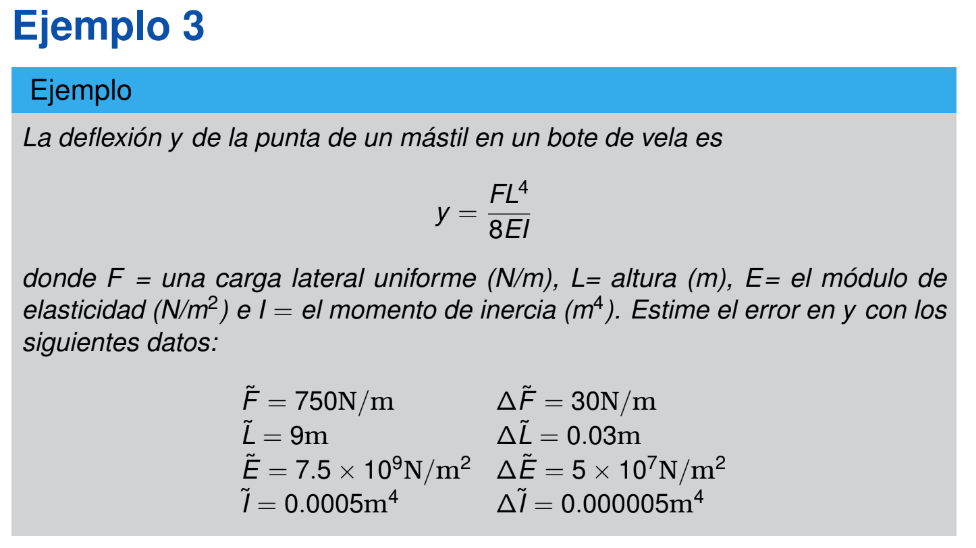

syms F L E I

%Funcion
y = @(F,L,E,I) (F*L^(4) / (8*E*I));

%Valores
F_val = 750;
L_val = 9;
E_val = 7.5 * 10^(9);
I_val = 0.0005;

%Errores Absolutos
eaF = 30;
eaL = 0.03;
eaE = 5 * 10^(7);
eaI = 0.000005;

%Derivada respecto a cada variable
dy_dF = matlabFunction(diff(y,F));
dy_dL = matlabFunction(diff(y,L));
dy_dE= matlabFunction(diff(y,E));
dy_dI = matlabFunction(diff(y,I));

%Error Absoluto de y

eay = abs(dy_dF(E_val,I_val,L_val)) * eaF + abs(dy_dL(E_val,F_val,I_val,L_val)) * eaL + abs(dy_dE(E_val,F_val,I_val,L_val)) * eaE + abs(dy_dI(E_val,F_val,I_val,L_val)) * eaI

eay = 0.0115

%Valores maximos y minimos que puede tomar y
maxY = y(F_val,L_val,E_val,I_val) + eay

maxY = 0.1755

minY = y(F_val,L_val,E_val,I_val) - eay

minY = 0.1525